# EE115 Lab 1

1) In this task, we will examine the average power of a random signal that has its minimum value larger than or equal to -1, and its impact n the power efficiency of the conventional AM signals. 

a) Use the Gaussian random generator to generate a random sequence $m\left\lbrack 0\right\rbrack ,m\left\lbrack 1\right\rbrack ,\ldotp \ldotp \ldotp ,m\left\lbrack N\right\rbrack$ where $N$ could be 200 or some other large integer

clear variables
% closes all figures
close all 
% Random seed, allows how to set a random seed for a random sequence. This
% means that we're always using the random seed of 0. This means that if I
% run the code multiple times I will get the same results. If you want
% different sequences comment this out
rng(0);
% Generates a sample (random sequence) from Gaussian distribution
m = randn(1,200)

m =     0.5377    1.8339   -2.2588    0.8622    0.3188   -1.3077   -0.4336    0.3426    3.5784    2.7694   -1.3499    3.0349    0.7254   -0.0631    0.7147   -0.2050   -0.1241    1.4897    1.4090    1.4172    0.6715   -1.2075    0.7172    1.6302    0.4889    1.0347    0.7269   -0.3034    0.2939   -0.7873    0.8884   -1.1471   -1.0689   -0.8095   -2.9443    1.4384    0.3252   -0.7549    1.3703   -1.7115   -0.1022   -0.2414    0.3192    0.3129   -0.8649   -0.0301   -0.1649    0.6277    1.0933    1.1093


b) Determine the minimum value of the sequence and denoote it by ${-M}_0$.

M_o = -min(m)

M_o = 2.9443

c)Compute the normalized sequence $m_n \left\lbrack k\right\rbrack =\frac{1}{M_0 }m\left\lbrack k\right\rbrack$ whose minimum value should be now -1

m_n_k = (1/M_o)*m;
norm_min_val = min(m_n_k)

norm_min_val = -1

d) Compute the average power of $m_n \left\lbrack k\right\rbrack$ by $P_m =\frac{1}{N}\sum_{k=1}^N m_n^2 \left\lbrack k\right\rbrack$

p = sum(m_n_k.^2);
p_m = (1/200)*p

p_m = 0.1360

*e) If we apply the conventional AM to  $m_n \left(t\right)=m_n \left\lbrack k\right\rbrack \mathrm{rect}\left(t-\mathrm{kT}\right)$ when rect(t) is a rectangular pulse of width equal to $T$, the transmitted signal is:


$$u_{\mathrm{AM}} \left(t\right)=A_c \left(a_{\mathrm{mod}} m_n \left(t\right)+1\right)\mathrm{cos}\left(2\pi f_c t\right)$$


and then its power efficiency is


$$\eta_{\mathrm{AM}} =\frac{a_{\mathrm{mod}} P_m }{1+a_{\mathrm{mod}} P_m }$$


Plot $\eta_{\mathrm{AM}}$ versus $0<P_m <1$ for each of $a_{\mathrm{mod}} =1,0,75,0\ldotp 5$

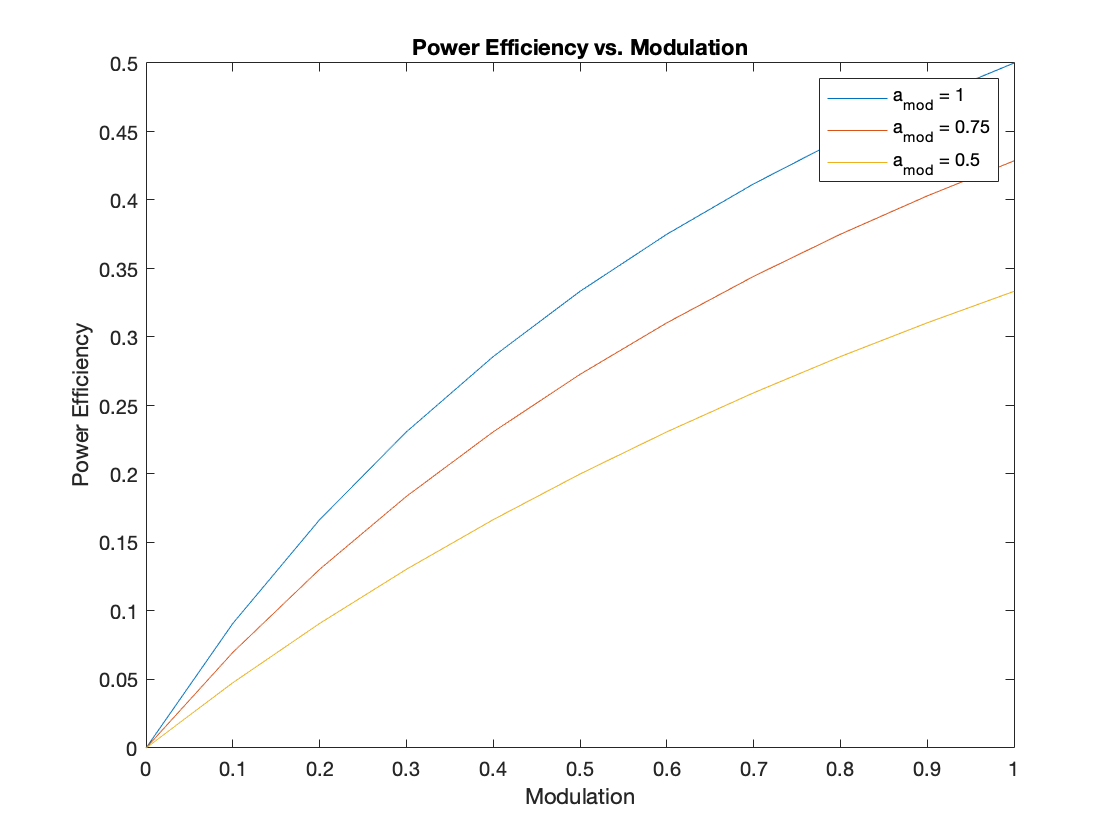

% Use the dot operator
% Since p_m is a variable use the range
pm = 0:0.1:1;
a_1 = 1;
plot_1 = (a_1*pm)./(1 + a_1*pm);
figure (1)
plot(pm,plot_1)
xlabel('Modulation')
ylabel('Power Efficiency')
title('Power Efficiency vs. Modulation')
hold all

a_2 = 0.75;
plot_2 = (a_2*pm)./(1 + a_2*pm);
plot(pm,plot_2)

a_3 = 0.5;
plot_3 = (a_3*pm)./(1 + a_3*pm);
plot(pm,plot_3)
legend('a_m_o_d = 1', 'a_m_o_d = 0.75', 'a_m_o_d = 0.5')

2) In this task, we will examine the quality of a simple DC blocker which consists of a capacitor $C$ and a resistor $R$ (in serial connection). We know that the frequency response $H\left(f\right)$ of the DC blocker is:


$$H\left(f\right)=\frac{\mathrm{j2}\pi f}{\mathrm{j2}\pi f+\frac{1}{\mathrm{RC}}}$$


a) Plot $\left|H\left(f\right)\right|$ versus $-50<f<50$ in Hz for each of $\mathrm{RC}=0\ldotp 01,0\ldotp 1,1,10$

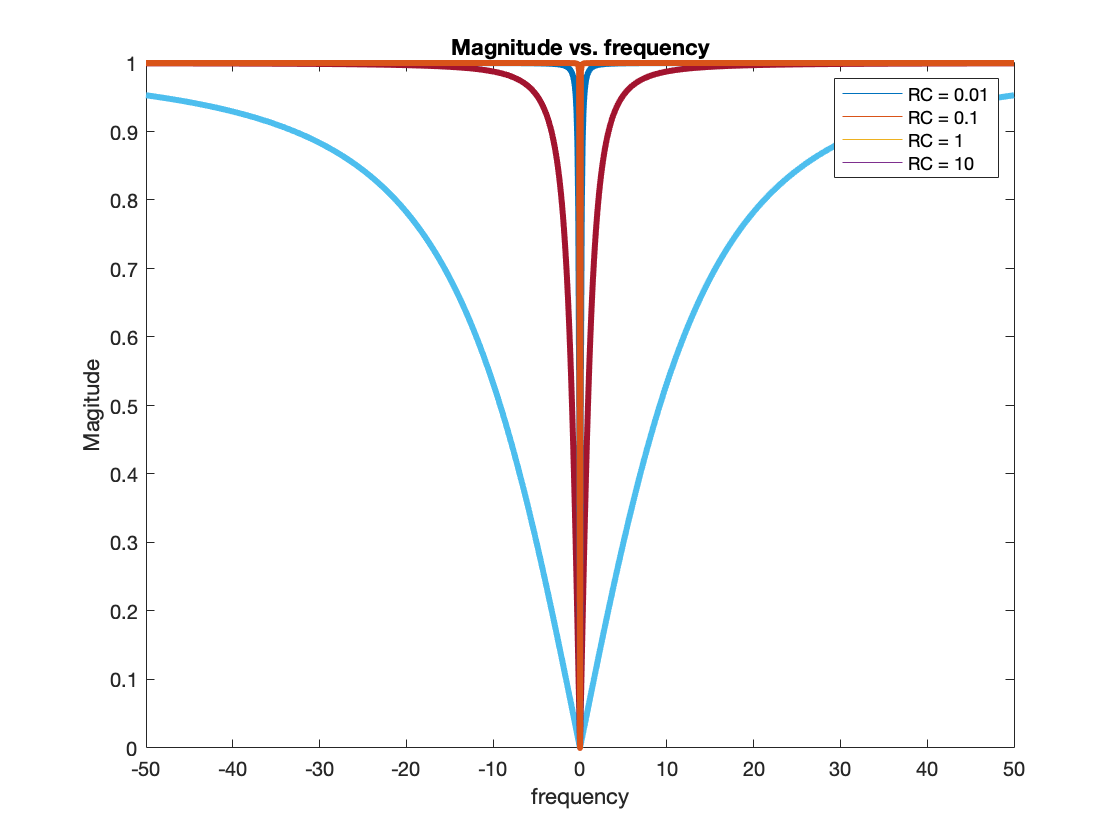

% to compute the magnitude us the abs function
frequency = -50:0.1:50;
RC_1 = 0.01;
H_F_1 = abs((1i*2*pi*frequency)./(1i*2*pi*frequency + (1/RC_1)));
figure (2)
plot(frequency, H_F_1, 'linewidth',3);
xlabel('frequency')
ylabel('Magnitude of |H(f)|')
title('Magnitude vs. frequency')
hold all

RC_2 = 0.1;
H_F_2 = abs((1i*2*pi*frequency)./(1i*2*pi*frequency + (1/RC_2)));
plot(frequency, H_F_2, 'linewidth',3);

RC_3 = 1;
H_F_3 = abs((1i*2*pi*frequency)./(1i*2*pi*frequency + (1/RC_3)));
plot(frequency, H_F_3, 'linewidth',3);

RC_4 = 10;
H_F_4 = abs((1i*2*pi*frequency)./(1i*2*pi*frequency + (1/RC_4)));
plot(frequency, H_F_4, 'linewidth',3);

legend('RC = 0.01', 'RC = 0.1', 'RC = 1', 'RC = 10')

b) If we want too remove the DC component from $$ where the spectrum of occupies the band from 20Hz to 5kHz, what shuld be an acceptable range of the RC values? (Provide a proper minimum value of RC.)

Because we want the DC component to not attenuate our signal at a frequency less than 20Hz, we need to use an inequality statement to determine what value of RC is acceptable:


$$\frac{1}{\mathrm{RC}}<20\mathrm{Hz}\Rightarrow \mathrm{RC}>\frac{1}{20\mathrm{Hz}}\Rightarrow \mathrm{RC}=0\ldotp 05\ldotp$$
 